# Calculate Joint Angles using Inverse Kinematics and Check with Rigid Body Tree

Here we calculate the joint angles from the left and right foot trajectories. 

We use an analytic solution of inverse kinematics for the leg based on [Closed-Form Inverse Kinematic Joint Solution for Humanoid Robots](https://ieeexplore.ieee.org/document/5649842) by Ali et. al. The function for inverse kinematics is called [`invKinBody2Foot`](matlab: edit invKinBody2Foot). The input to the simulation will be the feet transform matrix that contain position and orientation information. 

Finidng the analytic solution to the inverse kinematics requires deriving an expression based on the forward kinematics, which can be time consuming, difficult, and even impossible for some robot geometries and/or constraints. In that case, you may want to consider using the optimization-based [`inverseKinematics`](https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html) solver from Robotics System Toolbox. Although it is slower than the analytical solution, it can be applied to arbitrary kinematic chains with constraints. 

*Copyright 2019 The MathWorks, Inc.*

animateOn = false; 
speedupfactor = 12; % animation speed up 

% load default parameters if previous script wasn't run
if ~exist('footinfos','var')
    load('not_defaultfootinfos.mat')
end
% Assuming constraint bounds are already imported
% NOTE: make sure parameters match in inverse kinematics function 

% model = importrobot("robot.slx", "ConvertJoints", "convert-to-fixed");
% save('model.mat', 'model')
if ~exist('model','var')
    load('model.mat')
end
% initConfig = model.homeConfiguration;
% show(model, initConfig); 
initConfig = model.homeConfiguration

initConfig = 1×12 struct array with fields:
    JointName
    JointPosition


if ~exist('model_base','var')
    load('model_base.mat')
end
% initConfig = model.homeConfiguration;
% show(model, initConfig); 
initBaseConfig = model_base.homeConfiguration

initBaseConfig = 1×12 struct array with fields:
    JointName
    JointPosition


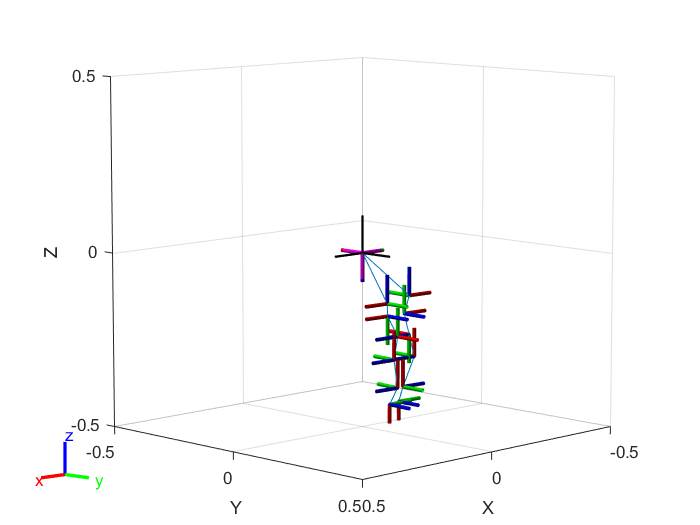

ans =   Axes (Primary) with properties:

             XLim: [-0.5000 0.5000]
             YLim: [-0.5000 0.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(model, initConfig)

showdetails(model)

--------------------
Robot: (13 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  Body08(8)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   
   8        Body08        Joint08       revolute            Body01(1)   Body09(9)  
   9        Body09        Joint09       revolute            Body08(8)   Body10(10)  
  10        Body10      

pGlobalOffset=model.Base.Children{1}.Joint.JointToParentTransform(1:3, 4)

pGlobalOffset = 1.0e-04 *

    0.0574
    0.1611
    0.4563


model.Base.Children{1}.Children{1}.Joint.JointToParentTransform(1:3, 4)

ans =    -0.0298
    0.1599
    0.1358


model.Base.Children{1}.Children{2}.Joint.JointToParentTransform(1:3, 4)

ans =    -0.0298
    0.0699
    0.1500


pLocalOffset=(model.Base.Children{1}.Children{1}.Joint.JointToParentTransform(1:3, 4)+model.Base.Children{1}.Children{2}.Joint.JointToParentTransform(1:3, 4))/2

pLocalOffset =    -0.0298
    0.1149
    0.1429


pLocalOffsetRotated = [pLocalOffset(2), pLocalOffset(1), pLocalOffset(3)]

pLocalOffsetRotated =     0.1149   -0.0298    0.1429


the destination p address  is p +pGlobalOffset-[plocaloffset[2], [1],[3]]

pOffset = pGlobalOffset-pLocalOffsetRotated.'

pOffset =    -0.1149
    0.0298
   -0.1429


pOffset= [pOffset(1), pOffset(2), pOffset(3)].'

pOffset =    -0.1149
    0.0298
   -0.1429


model.Base.Children{1}.Joint.JointToParentTransform

ans =     0.0000   -1.0000   -0.0000    0.0000
   -1.0000   -0.0000   -0.0000    0.0000
         0    0.0000   -1.0000    0.0000
         0         0         0    1.0000


footinfos{3}.footleft([1 3 5],:)

ans =    -0.0450   -0.0437   -0.0424   -0.0412   -0.0400   -0.0388   -0.0377   -0.0366   -0.0355   -0.0345   -0.0335   -0.0325   -0.0316   -0.0307   -0.0298   -0.0289   -0.0281   -0.0273   -0.0265   -0.0258   -0.0250   -0.0243   -0.0236   -0.0230   -0.0223   -0.0217   -0.0211   -0.0205   -0.0199   -0.0194   -0.0189   -0.0183   -0.0179   -0.0174   -0.0169   -0.0165   -0.0160   -0.0156   -0.0152   -0.0148   -0.0144   -0.0141   -0.0137   -0.0134   -0.0130   -0.0127   -0.0124   -0.0121   -0.0118   -0.0116
    0.0200    0.0194    0.0188    0.0182    0.0177    0.0172    0.0166    0.0161    0.0156    0.0152    0.0147    0.0143    0.0138    0.0134    0.0130    0.0126    0.0122    0.0118    0.0115    0.0111    0.0108    0.0104    0.0101    0.0098    0.0095    0.0092    0.0089    0.0086    0.0083    0.0081    0.0078    0.0076    0.0073    0.0071    0.0068    0.0066    0.0064    0.0062    0.0060    0.0058    0.0056    0.0054    0.0052    0.0050    0.0048    0.0047    0.0045    0.0043    0.0042   

jointConst = constraintJointBounds(model)

jointConst =   constraintJointBounds with properties:

     Bounds: [12×2 double]
    Weights: [1 1 1 1 1 1 1 1 1 1 1 1]


jointConst.Bounds

ans =    -3.1874   -0.0458
   -3.1416    0.0000
   -0.0000    3.1416
   -3.1379    0.0036
   -1.5744    1.5671
    0.0000    3.1416
   -0.0458    3.0958
    0.0000    3.1416
   -3.1416    0.0000
   -0.0034    3.1382


gik = generalizedInverseKinematics('RigidBodyTree', model, 'ConstraintInputs', {'pose','pose','joint'})

gik =   generalizedInverseKinematics with properties:

      NumConstraints: 3
    ConstraintInputs: {'pose'  'pose'  'joint'}
       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


gik.SolverParameters.AllowRandomRestart = false;
initialguess = model.homeConfiguration;
n = [0;  0; -1]; % x
s = [-1; 0; 0];  % y
a = [0;  1; 0];  % z
R = [n s a]; 
% Getting the first destination
% each step is a new index
% only get indices 1, 3, 5 since 2, 4, 6 is just a mirror of that
stateL = footinfos{1}.footleft([1 3 5],:)

stateL =    -0.0450   -0.0450   -0.0450   -0.0450   -0.0450   -0.0451   -0.0451   -0.0451   -0.0452   -0.0452   -0.0452   -0.0453   -0.0453   -0.0454   -0.0455   -0.0455   -0.0456   -0.0457   -0.0458   -0.0459   -0.0459   -0.0460   -0.0461   -0.0462   -0.0463   -0.0465   -0.0466   -0.0467   -0.0468   -0.0469   -0.0471   -0.0472   -0.0473   -0.0475   -0.0476   -0.0477   -0.0479   -0.0480   -0.0482   -0.0483   -0.0485   -0.0487   -0.0488   -0.0490   -0.0492   -0.0494   -0.0495   -0.0497   -0.0499   -0.0501
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

pL = stateL(:, 1)+pOffset

pL =    -0.1599
    0.0298
   -0.4729


transmatL =  [R     pL; 
                    [0 0 0 1]];
leftFoot = constraintPoseTarget('Body07', 'TargetTransform', transmatL)

leftFoot =   constraintPoseTarget with properties:

             EndEffector: 'Body07'
           ReferenceBody: ''
         TargetTransform: [4×4 double]
    OrientationTolerance: 0
       PositionTolerance: 0
                 Weights: [1 1]


stateR = footinfos{1}.footright([1 3 5],:); 
pR = stateR(:, 1)+pOffset

pR =    -0.0699
    0.0298
   -0.4729


transmatR =  [R     pR; [0 0 0 1]];
rightFoot = constraintPoseTarget('Body13', 'TargetTransform', transmatR)

rightFoot =   constraintPoseTarget with properties:

             EndEffector: 'Body13'
           ReferenceBody: ''
         TargetTransform: [4×4 double]
    OrientationTolerance: 0
       PositionTolerance: 0
                 Weights: [1 1]


pR

pR =    -0.0699
    0.0298
   -0.4729


pL

pL =    -0.1599
    0.0298
   -0.4729


pOffsetTranspose = pOffset.'

pOffsetTranspose =    -0.1149    0.0298   -0.1429


plotOffset = [pOffsetTranspose, 0]

plotOffset =    -0.1149    0.0298   -0.1429         0


[configSol,solInfo] = gik(initialguess, leftFoot, rightFoot, jointConst)

configSol = 1×12 struct array with fields:
    JointName
    JointPosition


solInfo = struct with fields:
              Iterations: 63
       NumRandomRestarts: 0
    ConstraintViolations: [1×3 struct]
                ExitFlag: 1
                  Status: 'best available'


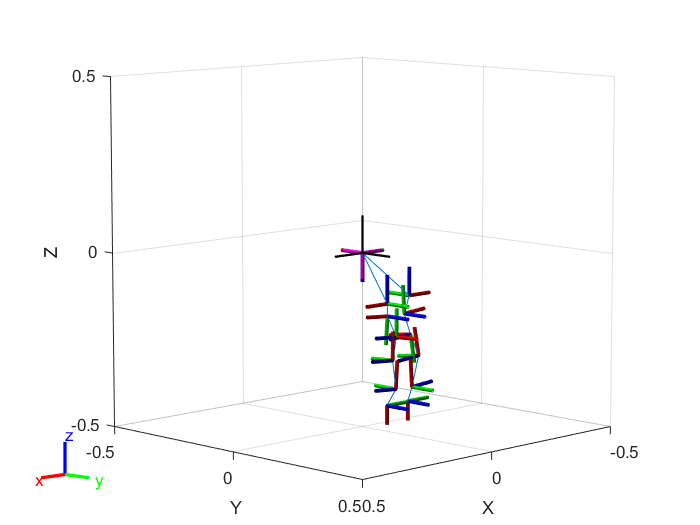

show(model, configSol, 'PreservePlot', false);

solInfo.ConstraintViolations

ans = 1×3 struct array with fields:
    Type
    Violation


solInfo.ConstraintViolations(3)

ans = struct with fields:
         Type: 'joint'
    Violation: [0 0 0 0 0 0 0 0 0 0 0 0]


## Show the Rigid Body Tree

% showdetails(robot)
hFig = figure; 
hFig.Visible = 'on'; 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0 0 0.4 0.4]; 
hFig

hFig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 0.4000 0.4000]
       Units: 'normalized'

  Show all properties


model.homeConfiguration

ans = 1×12 struct array with fields:
    JointName
    JointPosition


initialguess=model.homeConfiguration;

## Animate Joint Trajectory

Note that feet orientation is always normal to the ground. Also note the Z vector of the end effector is pointed toward the ground. 

currguess = initialguess

currguess = 1×12 struct array with fields:
    JointName
    JointPosition


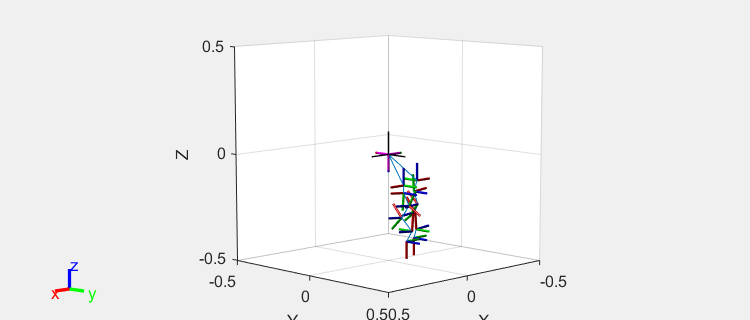

tic
    for sIdx = 1:length(footinfos)
        % Extract X Y Z position states (indices 1, 3, and 5)
        stateL = footinfos{sIdx}.footleft([1 3 5],:); 
        stateR = footinfos{sIdx}.footright([1 3 5],:); 
        stateL(2,:)=-stateL(2,:);
        stateR(2,:)=-stateR(2,:);
%       Going the opposite direction
        % Initialize matrices
        numIdx = size(stateL,2); 
        jointAngles = zeros(1, 12,numIdx);
        transMatLeft = zeros(4,4,numIdx); 
        transMatRight = zeros(4,4,numIdx); 
        
        % Skip some intermediate steps when visualizing 
        for idx = 1:numIdx
            % Get Left joints
            p = stateL(:,idx)+pOffset; 
            transmat =  [R     p; 
                        [0 0 0 1]];
            leftFoot = constraintPoseTarget('Body07', 'TargetTransform', transmat);
            transMatLeft(:,:,idx) = transmat; 
            
            % Get Right joints
            p = stateR(:,idx)+pOffset; 
            transmat =  [R     p; 
                        [0 0 0 1]];
            rightFoot = constraintPoseTarget('Body13', 'TargetTransform', transmat);
            transMatRight(:,:,idx) = transmat; 
            [currguess,solInfo] = gik(currguess, leftFoot, rightFoot, jointConst);
            for i = 1:12
                jointAngles(1, i, idx) = currguess(i).JointPosition-initialguess(i).JointPosition;
%                 jointAngles(1, i, idx) = -jointAngles(1, i, idx);
            end
            % Animate
            if animateOn
                if rem(idx,speedupfactor) == 0
                    show(model, currguess, 'PreservePlot', false, 'Position', plotOffset);
                    title('Walking Pattern Inverse Kinematics');
                    pause(0.001);
                end 
            end
        end
        % save joints info 
        footinfos{sIdx}.jointAngles = jointAngles;
        footinfos{sIdx}.transmatleft = transMatLeft; 
        footinfos{sIdx}.transmatright = transMatRight; 
    end
    show(model, currguess, 'PreservePlot', false);

toc

Elapsed time is 73.801453 seconds.


% Animate bot
currguess = initialguess

currguess = 1×12 struct array with fields:
    JointName
    JointPosition


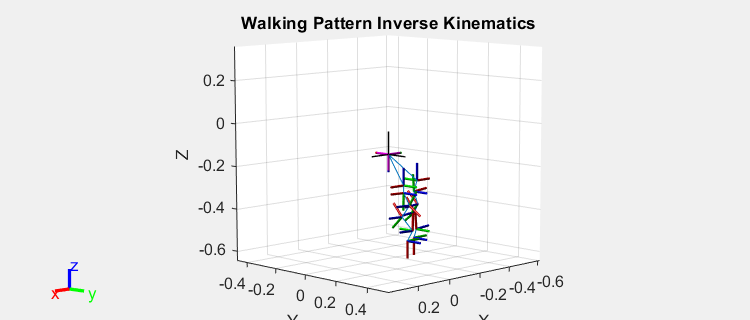

for sIdx = 1:length(footinfos)
    jointAngles = footinfos{sIdx}.jointAngles;
    numIdx = size(jointAngles, 3);
    for idx = 1:numIdx
        for i = 1:12
            currguess(i).JointPosition = jointAngles(1, i, idx)+initialguess(i).JointPosition;
        end
        if rem(idx,speedupfactor) == 0
            show(model, currguess, 'PreservePlot', false, 'Position', plotOffset);
            title('Walking Pattern Inverse Kinematics');
            pause(0.001);
        end
    end
end

## Create Simulation Input (End Effector)

The two variables used inside the simulation are end effector position and orientation information for the left leg and the right leg. This end effector position and orientation information is in the form of 4-by-4 transformation matrices. 

timeVec = footinfos{1}.timevec; 
jointAngles = footinfos{1}.jointAngles;

angleSignal.time = timeVec;
angleSignal.signals.values = jointAngles;
angleSignal.signals.dimensions = [1, 12];

for idx = 2:length(footinfos)
    timeVec = footinfos{idx}.timevec;
    jointAngles = footinfos{idx}.jointAngles;

    angleSignal.time = [angleSignal.time timeVec];
    angleSignal.signals.values = cat(3,angleSignal.signals.values, jointAngles);
end
angleSignal

angleSignal = struct with fields:
       time: [0 0.0050 0.0100 0.0150 0.0200 0.0250 0.0300 0.0350 0.0400 0.0450 0.0500 0.0550 0.0600 0.0650 0.0700 0.0750 0.0800 0.0850 0.0900 0.0950 0.1000 0.1050 0.1100 0.1150 0.1200 0.1250 0.1300 0.1350 0.1400 0.1450 0.1500 0.1550 0.1600 0.1650 … ]
    signals: [1×1 struct]


save('footinfos_with_jointangles.mat', 'footinfos')

angleSignal.signals

ans = struct with fields:
        values: [1×12×1361 double]
    dimensions: [1 12]


angleSignal.time

ans =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


save('angleSignal.mat', 'angleSignal')

## Helper Functions

function updateJoints(model, anglesright, anglesleft)
    
    desconfig = model.homeConfiguration; 
    for idx = 1:length(anglesright)
        desconfig(idx).JointPosition = desconfig(idx).JointPosition+anglesright(idx);
    end 
%     desconfig(1).JointPosition = desconfig(1).JointPosition - pi;
%     desconfig(2).JointPosition = desconfig(2).JointPosition + pi/2; 
%     
%     desconfig(8).JointPosition = pi;
    for idx = 1:length(anglesleft)
%         display(idx+6)
        desconfig(idx+6).JointPosition = desconfig(idx+6).JointPosition+anglesleft(idx);
    end 
%     desconfig(7).JointPosition = desconfig(7).JointPosition - pi; 
%     desconfig(8).JointPosition = desconfig(8).JointPosition + pi/2; 
       
    % update graphics 
%     display(desconfig)
    show(model, currguess, 'PreservePlot', false, 'Position', plotOffset);
%     show(robot, desconfig)
    title('Walking Pattern Inverse Kinematics')
    pause(0.001)
end